Basic Controller Design

% System Parameters
F_thrust = 27.6e3;    % 27.6 kN thrust
L = 4;                % Moment arm [m]
I = 9470;             % Inertia [kg·m²]

% Inner Loop (Pitch Rate Control)
sys_rate = tf(F_thrust*L/I, [1 0]);
C_rate = pidtune(sys_rate, 'PID', 30)


C_rate =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 2.53, Ki = 14.9
 
Continuous-time PI controller in parallel form.
Model Properties


inner_ol = C_rate * sys_rate;
inner_cl = feedback(inner_ol, 1);

% Outer Loop (Pitch Control)
sys_pitch = inner_cl * tf(1, [1 0]);
C_pitch = pidtune(sys_pitch, 'PI', 1.5)


C_pitch =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 1.29, Ki = 1.11
 
Continuous-time PI controller in parallel form.
Model Properties


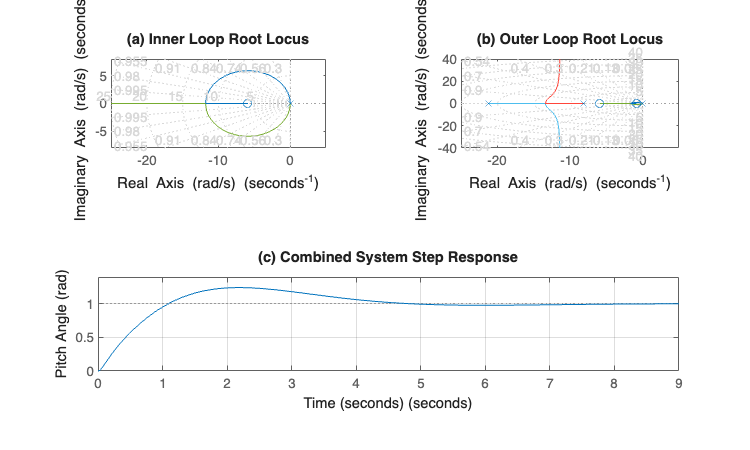

outer_ol = C_pitch * sys_pitch;
outer_cl = feedback(outer_ol, 1);

% Create figure with 2x1 subplot layout
figure('Position', [100 100 1000 600]);

% Inner Loop Root Locus
subplot(2,2,1)
rlocus(inner_ol)
title('(a) Inner Loop Root Locus')
xlabel('Real Axis (rad/s)')
ylabel('Imaginary Axis (rad/s)')
grid on

% Outer Loop Root Locus
subplot(2,2,2)
rlocus(outer_ol)
title('(b) Outer Loop Root Locus')
xlabel('Real Axis (rad/s)')
ylabel('Imaginary Axis (rad/s)')
grid on

% Combined Step Response
subplot(2,1,2)
step(outer_cl)
title('(c) Combined System Step Response')
xlabel('Time (seconds)')
ylabel('Pitch Angle (rad)')
grid on

Controller design with actuator nonlinearities

% First-order actuator model
tau = 0.01;  % Time constant in seconds (example value)
G_act = tf(1, [tau 1])  % Transfer function K/(τs+1) with K=1


G_act =
 
      1
  ----------
  0.01 s + 1
 
Continuous-time transfer function.
Model Properties




% Include first-order actuator dynamics in plant model
sys_rate_new = G_act * tf(F_thrust*L/I, [1 0])


sys_rate_new =
 
     11.66
  ------------
  0.01 s^2 + s
 
Continuous-time transfer function.
Model Properties



% Redesign controllers with the new plant model
C_rate_new = pidtune(sys_rate_new, 'PID', 20)  % Reduced bandwidth


C_rate_new =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 1.75, Ki = 6.44, Kd = 0.0159
 
Continuous-time PID controller in parallel form.
Model Properties


inner_ol_new = C_rate_new * sys_rate_new


inner_ol_new =
 
  0.1853 s^2 + 20.4 s + 75.08
  ---------------------------
        0.01 s^3 + s^2
 
Continuous-time transfer function.
Model Properties


inner_cl_new = feedback(inner_ol_new, 1)


inner_cl_new =
 
       0.1853 s^2 + 20.4 s + 75.08
  -------------------------------------
  0.01 s^3 + 1.185 s^2 + 20.4 s + 75.08
 
Continuous-time transfer function.
Model Properties



% Outer loop redesign
sys_pitch_new = inner_cl_new * tf(1, [1 0])


sys_pitch_new =
 
         0.1853 s^2 + 20.4 s + 75.08
  -----------------------------------------
  0.01 s^4 + 1.185 s^3 + 20.4 s^2 + 75.08 s
 
Continuous-time transfer function.
Model Properties


C_pitch_new = pidtune(sys_pitch_new, 'PI', 1.2)  % Adjusted bandwidth


C_pitch_new =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 1.02, Ki = 0.701
 
Continuous-time PI controller in parallel form.
Model Properties
